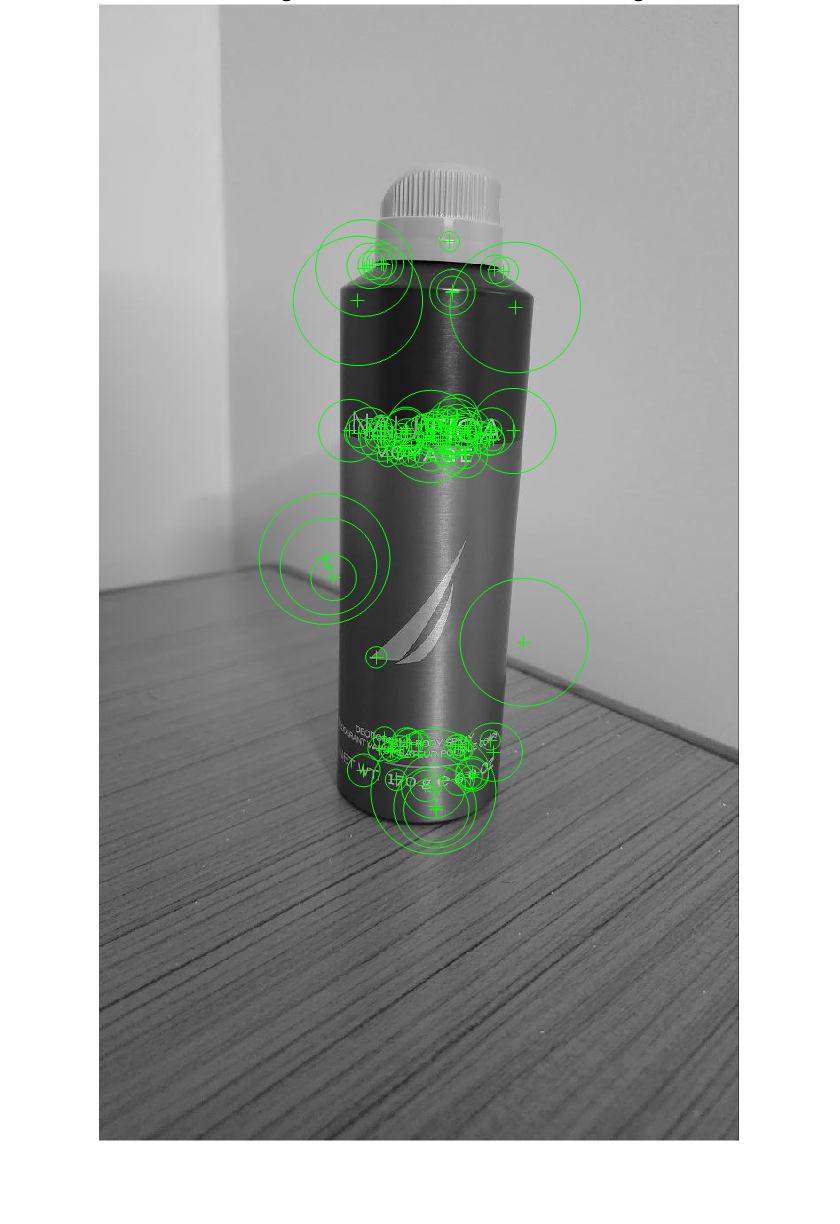


%% read images 
% Read the target image containing a cluttered scene.
vidReader = VideoReader('/Users/ishug/Desktop/hw3/q5_code/video_1/hw3_video.mp4','CurrentTime',1);
firstFrame = read(vidReader, 150);
sceneImage = rgb2gray(firstFrame); % in some versions, using im2grpy(frameRGB)

% Read the reference image containing the object of interest.
boxImage = imread('/Users/ishug/Desktop/hw3/q6_code/q6_image_1/1.jpg');
boxImage = rgb2gray(boxImage);


%% Step-2: Detect feature points in both images.
boxPoints = detectSURFFeatures(boxImage);
scenePoints = detectSURFFeatures(sceneImage);

% Visualize the strongest feature points found in the target image.
figure;
imshow(boxImage);
title('100 Strongest Feature Points from Box Image');
hold on;
plot(selectStrongest(boxPoints, 100));

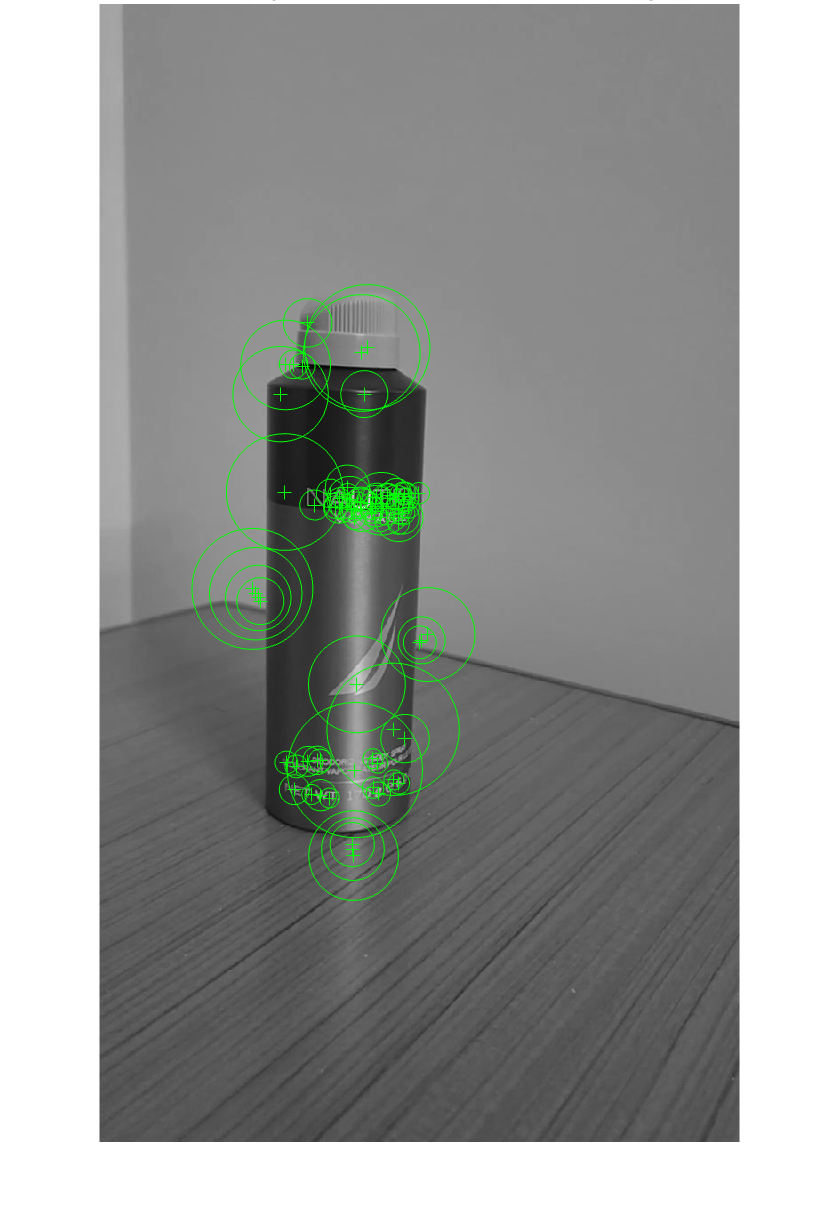


% Visualize the strongest feature points found in the target image.
figure;
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

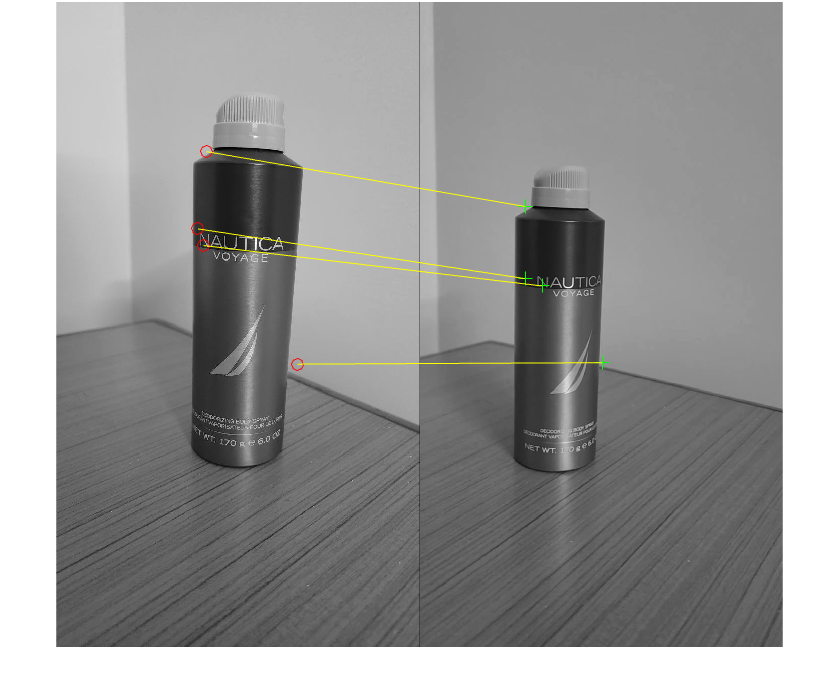


%% Step-3: Extract feature descriptors at the interest points in both images.
[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

%% Step-4: Match the features using their descriptors.
boxPairs = matchFeatures(boxFeatures, sceneFeatures);

% Display putatively matched features.
matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

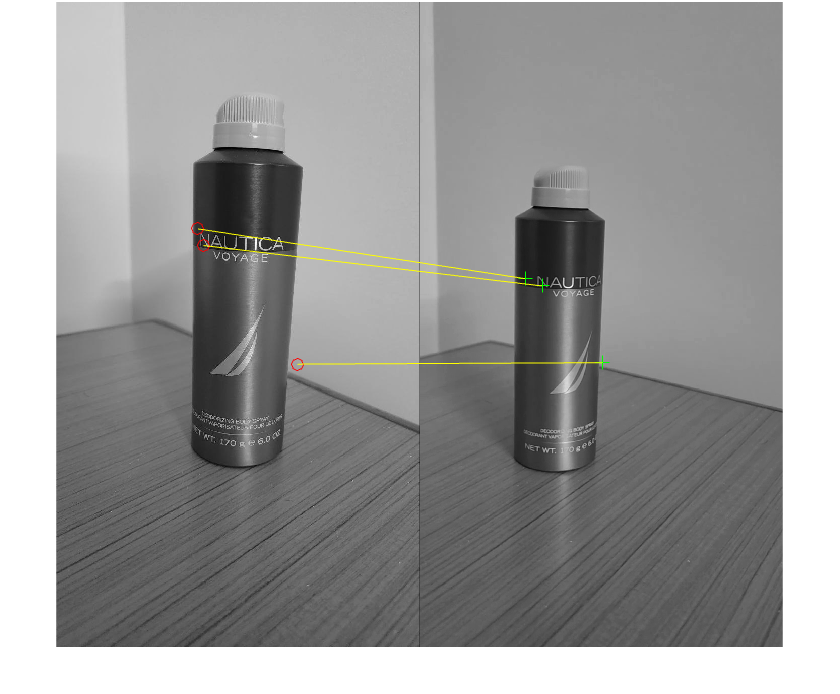


%% Step 5: Locate the Object in the Scene Using Putative Matches
[tform, inlierBoxPoints, inlierScenePoints] = estimateGeometricTransform(matchedBoxPoints, matchedScenePoints, 'affine');

figure;
showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

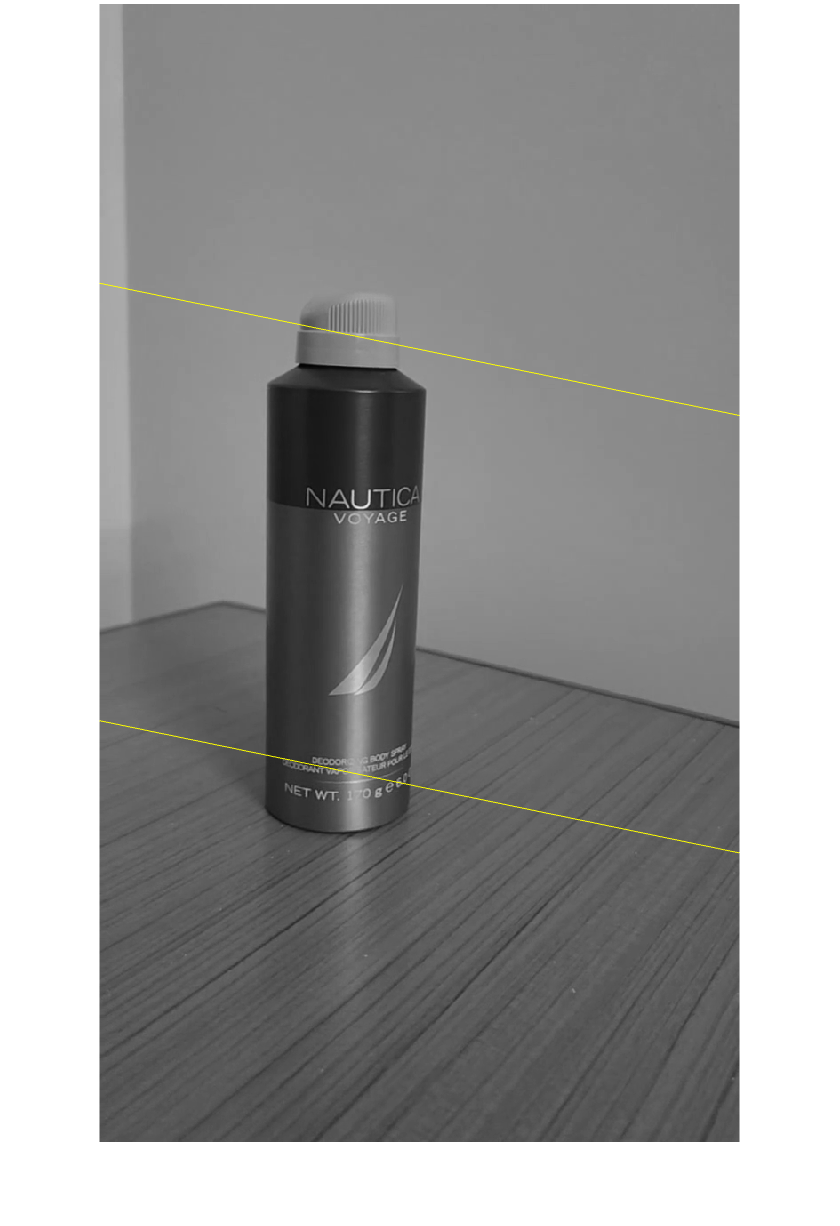


% Get the bounding polygon of the reference image.
boxPolygon = [1, 1;...                           % top-left
        size(boxImage, 2), 1;...                 % top-right
        size(boxImage, 2), size(boxImage, 1);... % bottom-right
        1, size(boxImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon
    
% Transform the polygon into the coordinate system of the target image. 
% The transformed polygon indicates the location of the object in the scene.
newBoxPolygon = transformPointsForward(tform, boxPolygon);

% Display the detected object.
figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'y');
title('Detected Box'); 